# Blue Whale Dashboard

Select a whale from the dataset below to see statistics and visualizations for elapsed time, travel distance and average speed.

load cleanWhaleData whales
whalesSummary = groupsummary(whales,"ID","range","latitude");
whalesSummary = sortrows(whalesSummary,'range_latitude','descend');

### Select a whale

whaleIDs = string(whalesSummary.ID);
id = whaleIDs(139);
rowsToKeep = whales.ID==id;
whale = whales(rowsToKeep,:);

### Select analysis options

doAnimation = true;
setGeoLimits = true;
distanceUnits = "km";
timeUnits = "hour";

### Select visualization options

pathLineStyle = "-";
pathLineWidth = 1;
pathMarker = "o";
pathMarkerSize = 6;
pathColor = "b" ;
markerColor = "r" ;

## Click Run to see results

### Data preview

whale

whale = 1×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    2004CA-Bmu-23036    2004-08-02 02:40:31.000     -123.66      38.222           B                  2             argos-doppler-shift          ""      


### Statistics table

% Get basic stats from table
numPoints = height(whale);
timeBounds = whale.timestamp([1 end]);
timeBounds.Format = "yyyy-MM-dd HH:mm";
latRange = range(whale.latitude);
lonRange = range(whale.longitude);

% Use custom function to calculate speed
[whale,kmPerDay] = whaleSpeed(whale);


% Make some new variables to hold values with converted units
avgSpeed = kmPerDay;
whale.elapsedDistance = whale.distance;
whale.elapsedTime = whale.elapsedDays;

% Change units
if distanceUnits == "mi"
    avgSpeed = avgSpeed / 1.61;
    whale.elapsedDistance = whale.elapsedDistance / 1.61;
end
if timeUnits == "year"
    avgSpeed = avgSpeed * 365;
    whale.elapsedTime = whale.elapsedTime / 365;
elseif timeUnits == "hour"
    avgSpeed = avgSpeed / 24;
    whale.elapsedTime = whale.elapsedTime * 24;
end

% Get values for total time and distance
totalTime = whale.elapsedTime(end);
totalDistance = whale.elapsedDistance(end);

% Assemble variables for stats table
speedUnits = distanceUnits + "/" + timeUnits;
rowNames = ["Number of Points","Time Start","Time End","Latitude Range (deg)", ...
    "Longitude Range (deg)","Elapsed time (" + timeUnits + "s)", ...
    "Distance Travelled (" + distanceUnits + ")","Speed (" + speedUnits + ")"];
statsValue = {numPoints; timeBounds(1); timeBounds(2); latRange; lonRange; ...
    totalTime; totalDistance; avgSpeed};

% Display table to user
statsTable = table(statsValue,'RowNames',rowNames)

statsTable = 8×1 table
                                    statsValue     
                               ____________________

    Number of Points           {[               1]}
    Time Start                 {[2004-08-02 02:40]}
    Time End                   {[2004-08-02 02:40]}
    Latitude Range (deg)       {[               0]}
    Longitude Range (deg)      {[               0]}
    Elapsed time (hours)       {[               0]}
    Distance Travelled (km)    {[               0]}
    Speed (km/hour)            {[               0]}


### Whale path visualization

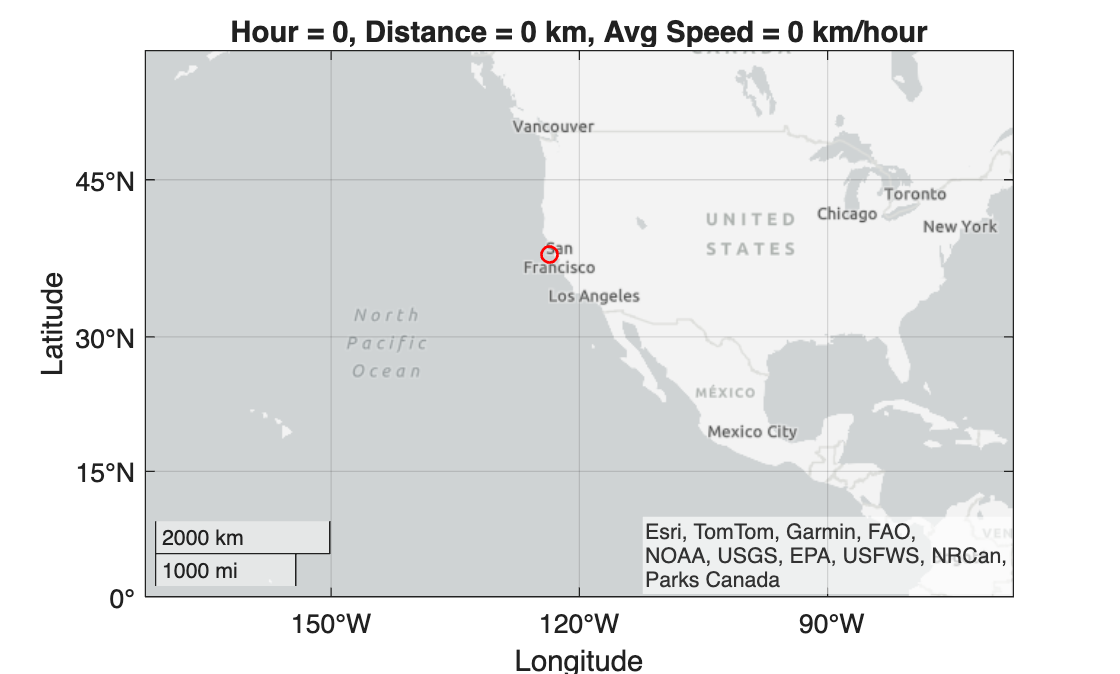

if doAnimation
    for ii = 1:height(whale)

        % Add line and markers
        geoplot(whale.latitude(ii),whale.longitude(ii),"Marker",pathMarker, ...
            "MarkerEdgeColor",markerColor,"LineStyle","none", ...
            "LineWidth",pathLineWidth,"MarkerSize",pathMarkerSize);
        hold on
        geoplot(whale.latitude(1:ii),whale.longitude(1:ii),"LineStyle",pathLineStyle, ...
            "LineWidth",pathLineWidth,"Color",pathColor)
        hold off

        % Set axes limits
        if setGeoLimits
            geolimits([0 55],[-150 -90])
        end
    
        % Add title with info
        timeUnits{1}(1) = upper(timeUnits{1}(1));
        timeValue = whale.elapsedTime(ii);
        if timeUnits == "Day" || timeUnits == "Hour"
            timeValue = round(timeValue);
        end
        titleStr = timeUnits + " = " + timeValue + ...
            ", Distance = " + round(whale.elapsedDistance(ii)) + " " + distanceUnits + ...
            ", Avg Speed = " + avgSpeed +  " " + speedUnits;
        title(titleStr)

        % Update plot (use faster option for whales with many points)
        if height(whale) >= 100
            drawnow limitrate
        else
            drawnow
        end
    end
else
    % Create static plot
    geoplot(whale.latitude,whale.longitude,"LineStyle",pathLineStyle, ...
        "Marker",pathMarker,"LineWidth",pathLineWidth, ...
        "Color",pathColor,"MarkerSize",pathMarkerSize, ...
        "MarkerEdgeColor",markerColor);
    title(id)
    if setGeoLimits
        geolimits([0 55],[-150 -90])
    end
end

*Copyright 2021 The MathWorks, Inc.*